# Data Eksplorasi dengan Matlab

T = readtable('D:\File\Bisa.AI\heart.csv')

T = 303×14 table
    age    sex    cp    trtbps    chol    fbs    restecg    thalachh    exng    oldpeak    slp    caa    thall    output
    ___    ___    __    ______    ____    ___    _______    ________    ____    _______    ___    ___    _____    ______

    63      1     3      145      233      1        0         150        0        2.3       0      0       1        1   
    37      1     2      130      250      0        1         187        0        3.5       0      0       2        1   
    41      0     1   

Features of data:

- age - age in years

- sex - sex (1 = male; 0 = female)

- cp - chest pain type (1 = typical angina; 2 = atypical angina; 3 = non-anginal pain; 0 = asymptomatic)

- trestbps - resting blood pressure (in mm Hg on admission to the hospital)

- chol - serum cholestoral in mg/dl

- fbs - fasting blood sugar > 120 mg/dl (1 = true; 0 = false)

- restecg - resting electrocardiographic results (1 = normal; 2 = having ST-T wave abnormality; 0 = hypertrophy)

- thalach - maximum heart rate achieved

- exang - exercise induced angina (1 = yes; 0 = no)

- oldpeak - ST depression induced by exercise relative to rest

- slope - the slope of the peak exercise ST segment (2 = upsloping; 1 = flat; 0 = downsloping)

- ca - number of major vessels (0-3) colored by flourosopy

- thall - 2 = normal; 1 = fixed defect; 3 = reversable defect

- num - the predicted attribute - diagnosis of heart disease (angiographic disease status) (Value 0 = < diameter narrowing; Value 1 = > 50% diameter narrowing)

[Sumber](https://www.kaggle.com/rashikrahmanpritom/heart-attack-analysis-prediction-dataset)

T.Properties.VariableNames         % extract column names

ans = 1×14 cell array
    {'age'}    {'sex'}    {'cp'}    {'trtbps'}    {'chol'}    {'fbs'}    {'restecg'}    {'thalachh'}    {'exng'}    {'oldpeak'}    {'slp'}    {'caa'}    {'thall'}    {'output'}


% choose the categorical columns
cat = {'sex','cp','fbs','restecg','exng','slp','caa','thall'};
% choose the numerical columns
num = {'age','trtbps','chol','thalachh','oldpeak'};

Visualisasi Data Numerical

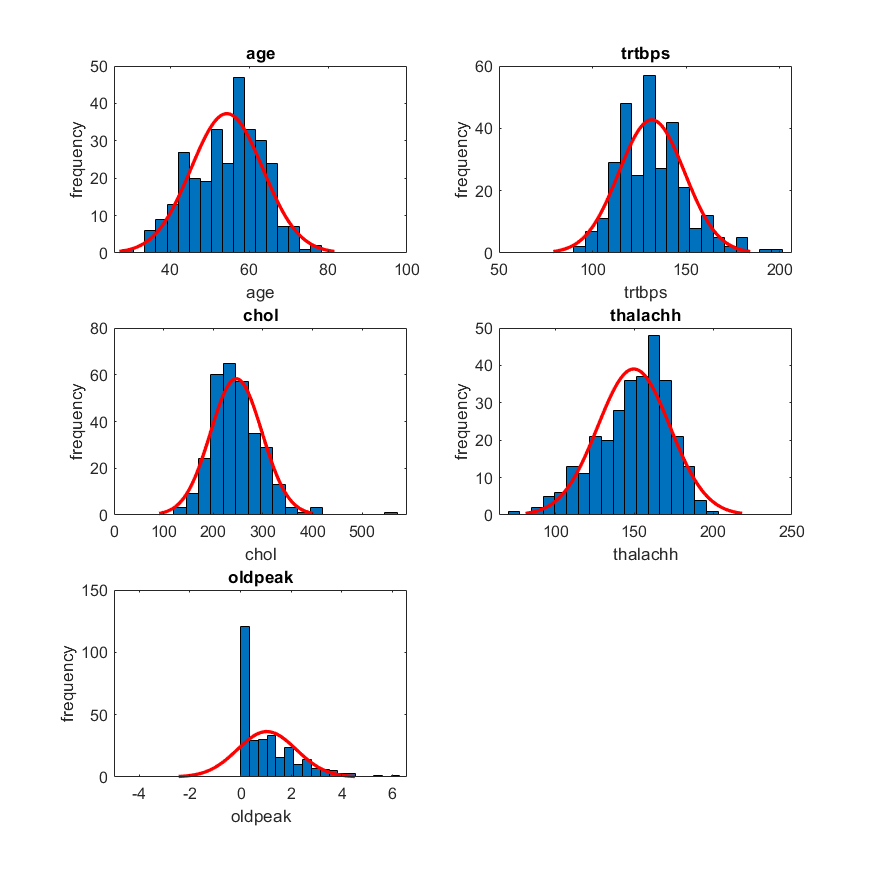

for i = 1:numel(num)
    subplot(3,2,i)
    histfit(table2array(T(:,{num{i}})))
    xlabel(num{i})
    ylabel('frequency')
    title(num{i})
end
set(gcf,'Position',[100 100 700 700])

Visualisasi Data Categorical

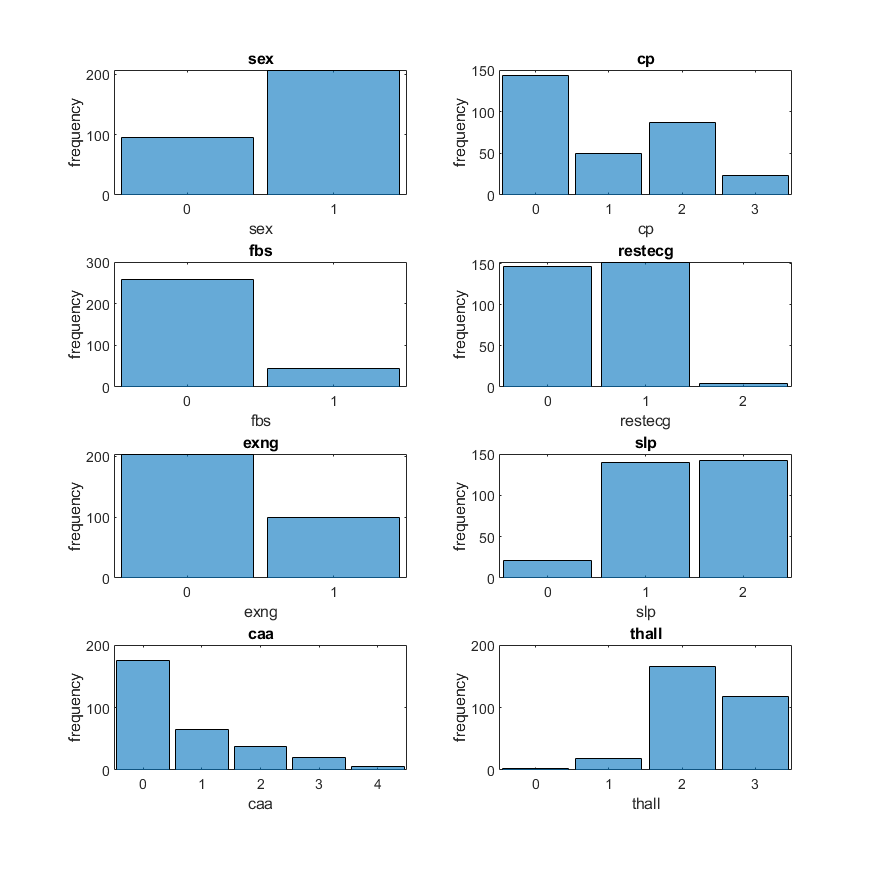

for i = 1:numel(cat)
    subplot(4,2,i)
    histogram(categorical(table2array(T(:,{cat{i}}))))
    xlabel(cat{i})
    ylabel('frequency')
    title(cat{i})
end 

set(gcf,'Position',[100 100 700 700])

Distribution of Features with regard to Output